# 蓝牙指纹定位主函数

## 导入指纹数据并进行预处理

if false
    load(['D:\Code\BlueTooth\pos_bluetooth_matlab\Fingerprinting\Data\', ...
        'ble_data_base_least.mat'], 'data');
    data_in = data;
else
    load(['D:\Code\BlueTooth\pos_bluetooth_matlab\Fingerprinting\Data\', ...
        'ble_data_base_least_completion.mat'], 'data_new');
    data_in = data_new;
end

% ble_data_base_least_completion
% 2.数据预处理
% 调用cell2mat转换完之后的数据格式:
% ['Beacon0','Beacon1','Beacon6','Beacon7','POS_X','POS_Y']
% [-66,-42,-62,-65,0,0]
data_mat = cell2mat(data_in);
ble_figureprinting_train = data_mat(:, 1:4); % 特征数据
ble_labels_train = strings(0);

% 将数组坐标[x,y]转换为字符串坐标"x:x-y:x"
for k = 1:1:length(ble_figureprinting_train)
    ble_labels_train(k) = strcat("x:", num2str(data_mat(k, 5)), ...
        ",", "y:", num2str(data_mat(k, 6)));
end

ble_labels_train = reshape(ble_labels_train, ...
    [length(ble_labels_train), 1]);

## knnsearch lose rate 验证

% lose rate
losr_rate = zeros(0);

for k = 1:20
    n_neigherbors = k;
    rng(100);
    Mdl = fitcknn(ble_figureprinting_train, ble_labels_train, 'NumNeighbors', n_neigherbors);
    loss = resubLoss(Mdl);
    losr_rate(k) = loss;
    rng(10); % For reproducibility
    CVMdl = crossval(Mdl, 'KFold', 5);
    kloss = kfoldLoss(CVMdl);
end
figure('Name','sd')
plot(1:1:20,losr_rate)

## KNN Kd-Tree实现

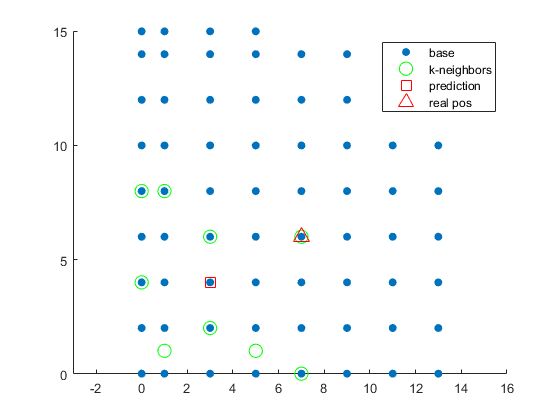

n_neigherbors = 9;
% [-60	-56	-59	-65],[7,6]
test_fingerprinting = [-60	-56	-59	-65];
grid_pos_prediction = ble_knn_classify(test_fingerprinting, n_neigherbors, 'truepos', [7, 6]);

pdist2(grid_pos_prediction, [7, 6], 'euclidean')

ans =           4.47213595499958


## KNN Kd-Tree验证

1.说明:验证k和预测偏差的关系

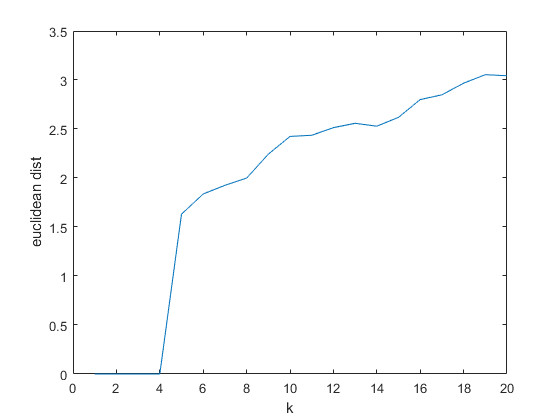

prediction_dist = zeros(0);

for k = 5:20
    n_neigherbors = k;
    % [-60	-56	-59	-65],[7,6]
    test_fingerprinting = [-60	-56	-59	-65];
    grid_pos_prediction = ble_knn_classify(test_fingerprinting, n_neigherbors, 'reverse_distance','truepos', [7, 6]);
    prediction_dist(k) = pdist2(grid_pos_prediction, [7, 6], 'euclidean');
end

figure()
plot(prediction_dist)
set(get(gca, 'XLabel'), 'String', 'k');
set(get(gca, 'YLabel'), 'String', 'euclidean dist');

## 权重系数—高斯函数

`gaussian` `函数参数说明`

`a:曲线的高度`

`b:曲线中心线在x轴的偏移`

`c:半峰宽度(函数峰值一半处相距的宽度)`

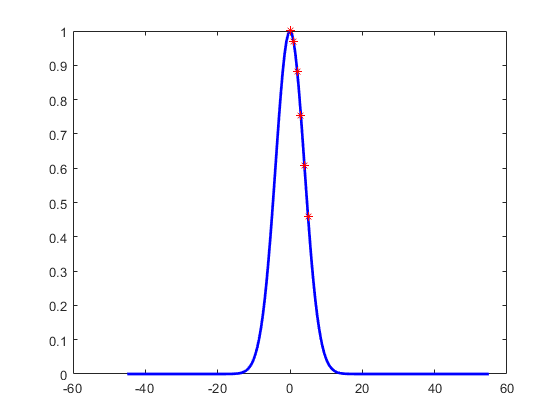

f_gaussian = @(x, a, b, c)(a * exp((-0.5 .* (x - b).^2) / c^2));
x_gaussian = -45:0.5:55;
y_gaussian = f_gaussian(x_gaussian, 1, 0, 4);
x_real = [0,1,2,3,4,5];
y_real = f_gaussian(x_real,1, 0, 4);
tcf('gaussian-1');
figure('Name','gaussian-1')
plot(x_gaussian, y_gaussian, 'Linewidth', 2,'Color','b')
hold on
plot(x_real,y_real,'Linestyle','none','Marker','*','Color','r')

w1 = get_weights([1,2,3],'uniform',3);
w1 = w1./sum(w1)

w1 =          0.333333333333333         0.333333333333333         0.333333333333333


w2 = get_weights([1,2,3],'gaussian',3);
w2 = w2./sum(w2)

w2 =          0.371842433354426          0.33856638836997         0.289591178275604


w3 = get_weights([1,2,3],'reverse_distance',3);
w3 = w3./sum(w3)

w3 =          0.492957746478873         0.295774647887324         0.211267605633803


# bluetooth_fingerprinting

a = bluetooth_fingerprinting(5);
b = a.knn_prediction(1)

未定义函数或变量 'weight_select'。

出错 bluetooth_fingerprinting/knn_prediction (line 140)
                weight_select);

# 自定义函数

function weights_cof = get_weights(dist, weight_select, n_neigherbors, varargin)
    % weights_cof = np.ones([1, n_neigherbors])
    weights_cof = ones(1, n_neigherbors);
    % 相同权重
    if strcmpi(weight_select, 'uniform')
        weights_cof = 1 ./ weights_cof;
    end

    % 高斯权重
    if strcmpi(weight_select, 'gaussian')
        % 高斯函数,a:曲线的高度,b:曲线中心线在x轴的偏移,c:半峰宽度(函数峰值一半处相距的宽度)
        gaussian_f = @(x, a, b, c)(a * exp((-0.5 .* (x - b).^2) / c^2));
        weights_cof = gaussian_f(dist, 1, 0, 4);
    end

    % 距离反比
    if strcmpi(weight_select, 'reverse_distance')
        % 避免/0
        off_side = 0.5;
        weights_cof = 1 ./ (dist + off_side);
    end

end


`gaussian`` 函数`

function weight_value = gaussian_weight(dist, a, b, c)
    weight_value = a * exp((-0.5 .* (dist - b).^2) / c^2)
end